# **Visión Artificial - Sistemas de Visión Artificial**

# **Práctica 3. Segmentación de imágenes (I)**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel.**

 **Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es):  Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:** 30/10/2026

El **objetivo** principal de esta práctica es familiarizarse con las técnicas de segmentación de imágenes:

- Desde métodos supervisados, que utilizan información previa sobre las clases para determinar los parámetros de la segmentación, hasta métodos no supervisados, que obtienen dichos parámetros automáticamente a partir de los datos.

- Técnicas basadas en el histograma, técnicas de agrupamiento (*clustering*), técnicas basadas en regiones y técnicas basadas en bordes.

- Basadas en métodos lineales y no lineales de clasificación de cada píxel de la imagen en la región que le corresponda.

 A lo largo de la práctica se solicitará que:

- Se apliquen, de forma práctica algunas de las técnicas de segmentación estudiadas, verificando la problemática y limitaciones de las mismas.

- Se comparen unas técnicas de segmentación con otras, analizando sus resultados.

- Se distinga la segmentación supervisada frente a la no supervisada.

- Se diferencie la segmentación basada en técnicas lineales frente a no lineales.

Se recomienda realizar pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), analizar los problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. Realice cada ejercicio como sección independiente, visualizando los resultados conjuntamente con subplot cuando sea conveniente, e insertando instrucciones para cerrar ventanas (*close all*), eliminar las variables del *workspace* (*clear all*) y pausar (*pause*), donde considere necesario.

La **entrega** se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

**Ejercicios propuestos:**

**1. Segmentación global supervisada basada en el histograma:**

- Abra la imagen "`esferas.jpg`".

- Conviértala en imagen en niveles de gris.

- Calcule y muestre el histograma de la imagen en niveles de gris.

- A la vista del histograma, utilice tantos umbrales como sean necesarios, con los valores adecuados para separar las distintas clases (ignorando el efecto de sombras y brillos). Puede introducirlos con un control deslizante (*numeric slider*) o pidiéndolos en el prompt de Matlab con la instrucción: umbral = input('Introduce valor del umbral X a la vista de la figura del histograma ').

- Visualice la segmentación.

- ¿Es fácil segmentar los distintos objetos? ¿Es fácil aislar la esfera de color azul? Justifique su respuesta.

- Visualice la imagen en color y muestre por separado las componentes R, G y B y el histograma de cada componente. Segmente la esfera azul a partir del histograma de la componente más conveniente. ¿Es fácil de segmentar en este caso? ¿Qué conclusión puede extraer sobre la importancia de elegir adecuadamente las características utilizadas para segmentar?

clear all
close all

info = imfinfo('.\Imagenes\Esferas.jpg');
disp(info.ColorType);

X=imread('.\Imagenes\Esferas.jpg');
greyimg=im2gray(X);

figure;
subplot(1,2,1), imshow(X);
subplot(1,2,2), imshow(greyimg);
% Histograma de la imagen en niveles de gris
figure;
imhist(greyimg);
title('Histograma de la imagen en niveles de gris');

% Modificamos los umbrales con los controles deslizantes del Live Editor.
T1 = 84; % roja | verde-azul, p. ej. 84
T2 = 165; % verde-azul | amarilla, p. ej. 165
T3 = 238; % amarilla | fondo, p. ej. 238


% Dibujamos los umbrales sobre el histograma para comprobar que caen en los valles
figure;
imhist(greyimg);
hold on

truecolor


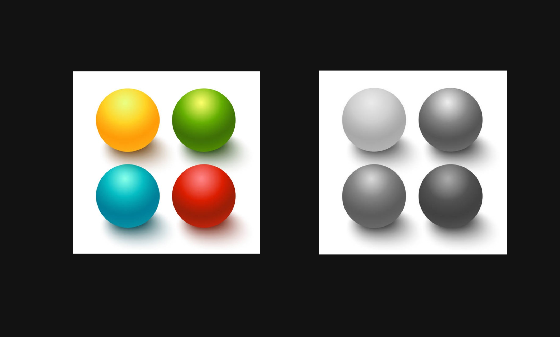

xline(T1, 'r');
xline(T2, 'r');
xline(T3, 'r');
hold off
title('Histograma con los umbrales elegidos');

% Segmentación: imagen de etiquetas

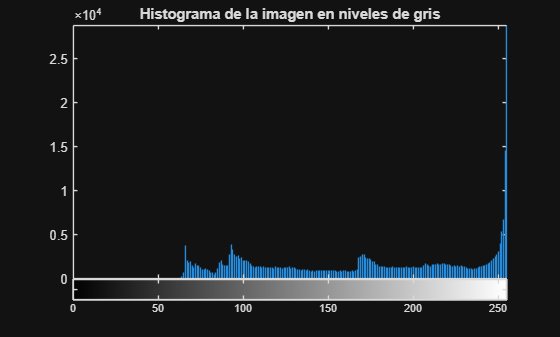

% Cada píxel recibe un número según el intervalo en el que cae su nivel de gris
etiquetas = zeros(size(greyimg)); % empezamos con todo a 0
etiquetas(greyimg <= T1) = 1; % clase 1: esfera roja
etiquetas(greyimg > T1 & greyimg <= T2) = 2; % clase 2: esferas verde y azul

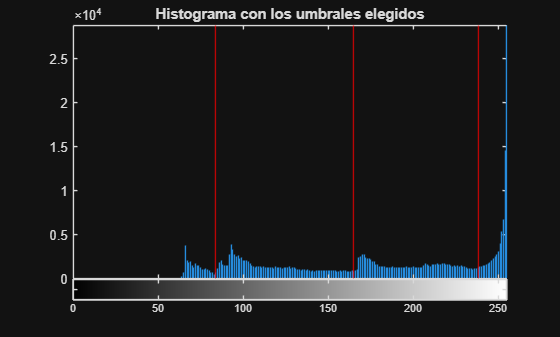

etiquetas(greyimg > T2 & greyimg <= T3) = 3; % clase 3: esfera amarilla
etiquetas(greyimg > T3) = 4; % clase 4: fondo


figure;
subplot(1,2,1), imshow(X); title('Original');
subplot(1,2,2), imshow(etiquetas, []);  % [] reparte las etiquetas entre negro y blanco (escala de gris)
colormap(gca, jet); colorbar; % paleta de colores para distinguir las clases
title('Segmentación en niveles de gris (4 clases)');

% Componentes R, G y B y sus histogramas
R = X(:,:,1);
G = X(:,:,2);
B = X(:,:,3);

figure;

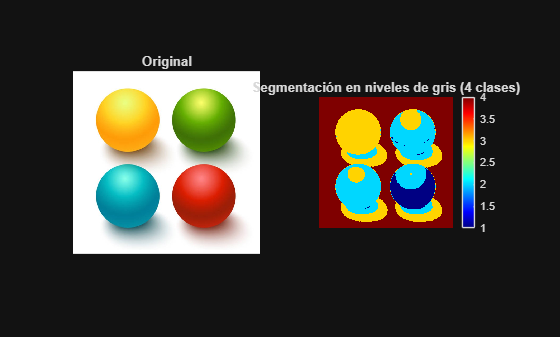

subplot(2,3,1), imshow(R); title('Componente R');
subplot(2,3,2), imshow(G); title('Componente G');
subplot(2,3,3), imshow(B); title('Componente B');
subplot(2,3,4), imhist(R); title('Histograma R');
subplot(2,3,5), imhist(G); title('Histograma G');
subplot(2,3,6), imhist(B); title('Histograma B');

%  Segmentar la esfera azul con la componente R
% La esfera azul es la única sin apenas rojo (R casi 0): forma un pico aislado
% en el extremo izquierdo del histograma de R. Basta un umbral.
TR = 55; % umbral de la componente R, por ejemplo 55

mascaraAzul = R <= TR; % 1 = esfera azul, 0 = resto

% Para verla en color: multiplicamos la imagen por la máscara (lo que no es azul queda negro)

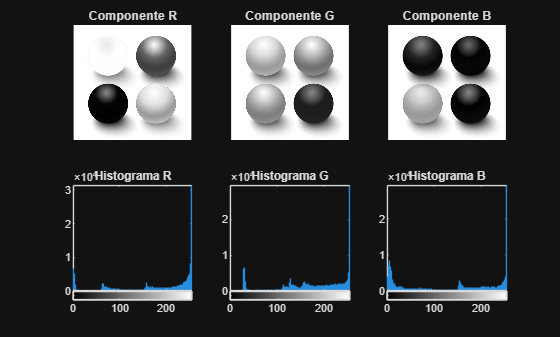

esferaAzul = X .* uint8(mascaraAzul);

figure;
subplot(1,3,1), imshow(X); title('Original');
subplot(1,3,2), imshow(mascaraAzul); title(['Máscara: R <= ' num2str(TR)]);
subplot(1,3,3), imshow(esferaAzul); title('Esfera azul segmentada');
%% PRUEBA EXTRA: segmentar todas las esferas usando R, G y B
% Cada esfera se define con una condición sobre cada componente, y se combinan con AND (&).
% Valores aproximados de cada esfera (observados en los histogramas de R, G y B):
%   Amarilla: R muy alto, G alto,      B bajo
%   Roja:     R alto,     G bajo,      B bajo
%   Verde:    R medio,    G alto,      B bajo
%   Azul:     R casi 0

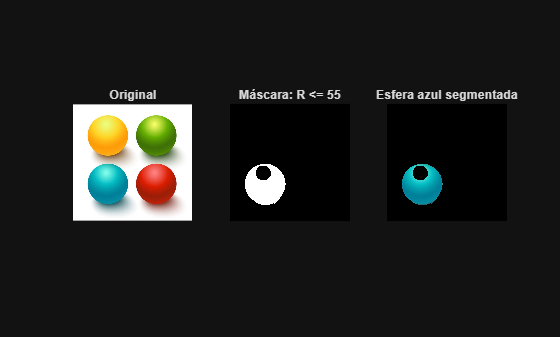

% El fondo blanco tiene R, G y B altos, y las sombras grises R ≈ G ≈ B,
% así que la condición "B bajo" (B < 140) las descarta (en general) en las tres primeras esferas.

mascaraAmarilla = (R > 200) & (G > 140) & (B < 140);
mascaraRoja = (R > 150) & (G < 140) & (B < 140);
mascaraVerde = (R < 150) & (G > 100) & (B < 110);
mascaraAzul = (R <= 55);

% Imagen de etiquetas: 0 = fondo, 1 = amarilla, 2 = verde, 3 = azul, 4 = roja
etiquetasRGB = zeros(size(R));
etiquetasRGB(mascaraAmarilla) = 1;
etiquetasRGB(mascaraVerde) = 2;
etiquetasRGB(mascaraAzul) = 3;
etiquetasRGB(mascaraRoja) = 4;


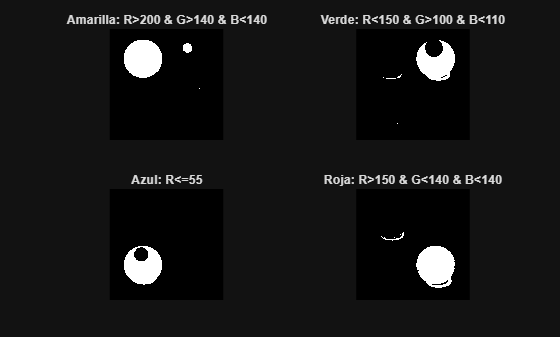

% Máscaras por separado
figure;
subplot(2,2,1), imshow(mascaraAmarilla); title('Amarilla: R>200 & G>140 & B<140');
subplot(2,2,2), imshow(mascaraVerde);    title('Verde: R<150 & G>100 & B<110');
subplot(2,2,3), imshow(mascaraAzul);     title('Azul: R<=55');
subplot(2,2,4), imshow(mascaraRoja);     title('Roja: R>150 & G<140 & B<140');

% Resultado conjunto comparado con la segmentación en gris de antes
figure;
subplot(1,3,1), imshow(X); title('Original');
subplot(1,3,2), imshow(etiquetas, []); colormap(gca, jet); title('Gris (4 clases)');
subplot(1,3,3), imshow(etiquetasRGB, []); colormap(gca, jet); title('RGB (5 clases)');

%% PRUEBA EXTRA: ¿y si usamos la componente B, que parece la "lógica"?
% El fondo blanco y las sombras grises también tienen B alto -> se mezclan con la esfera
mascaraB = (B > 145) & (B <= 240);

figure;
subplot(1,2,1), imshow(mascaraB); title('Esfera azul usando B (145 < B <= 240)');
subplot(1,2,2), imshow(mascaraAzul); title('Esfera azul usando R (R <= 55)');

%% PRUEBA EXTRA: espacio HSV (tono + saturación) combinando máscaras con AND
% H = tono (qué color es), S = saturación (cuánto color tiene; el blanco y el gris tienen S baja)
hsv = rgb2hsv(X); % valores entre 0 y 1
H = hsv(:,:,1);
S = hsv(:,:,2);

figure;

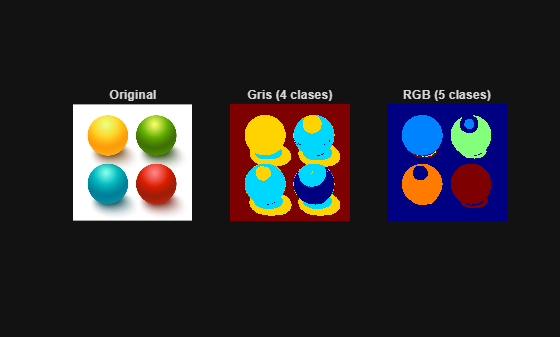

subplot(1,2,1), imhist(H); title('Histograma de H (tono)');
subplot(1,2,2), imhist(S); title('Histograma de S (saturación)');

% Histograma del tono solo para píxeles con color (S alta):
% así eliminamos el fondo blanco, que tiene H = 0 y tapa todo lo demás
figure;

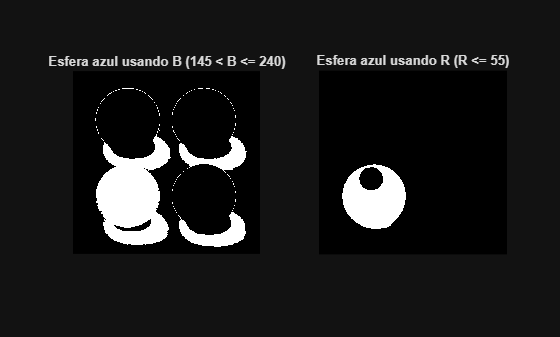

imhist(H(S > 0.40));
title('Histograma de H solo de los píxeles saturados (S > 0.40)');
% H es un ángulo de 0° a 360°, que MATLAB guarda entre 0 y 1.
% Los colores puros caen en valores fijos: rojo ≈ 0 (o 1), amarillo ≈ 0,17, verde ≈ 0,33, cian ≈ 0,5 y azul ≈ 0,67.

mascaraTono = (H > 0.40) & (H < 0.60); % tonos cian/azulados
mascaraSat = S > 0.40; % descartamos fondo y sombras (poco saturados)
mascaraHSV = mascaraTono & mascaraSat; % AND de las dos condiciones


figure;
subplot(1,3,1), imshow(mascaraTono); title('Solo tono H');
subplot(1,3,2), imshow(mascaraHSV); title('Tono H AND saturación S');
subplot(1,3,3), imshow(X .* uint8(mascaraHSV)); title('Esfera azul (HSV)');

En este apartado se ha segmentado la imagen “Esferas.jpg” mediante umbralización global supervisada: los umbrales se han elegido observando el histograma.

En niveles de gris el histograma muestra cuatro poblaciones: la esfera roja, un lóbulo único que agrupa las esferas verde y azul, la esfera amarilla y el fondo blanco. Con tres umbrales (T1 = 84, T2 = 165, T3 = 238) se obtienen cuatro clases. La esfera roja, la amarilla y el fondo se separan aceptablemente, aunque los brillos y las sombras se asignan a clases incorrectas, porque el histograma no contiene información espacial ni de color. En cambio, en niveles de gris no es posible aislar la esfera azul de la verde, ya que sus luminancias coinciden y sus distribuciones se solapan casi por completo, de modo que ningún umbral las separa.

Al analizar por separado las componentes R, G y B, la componente R resulta la más discriminante: la esfera azul es el único objeto con R prácticamente nulo y forma un pico aislado en el histograma, así que basta un único umbral (R ≤ 55) para segmentarla con precisión. Como prueba adicional se comprobó que la componente B, aparentemente la más lógica, da peores resultados, porque el fondo y las sombras también tienen valores altos de azul.

En el espacio HSV, combinando con una operación AND una condición sobre el tono (0,40 < H < 0,60) y otra sobre la saturación (S > 0,40), se obtiene la esfera completa, incluido el brillo.

Se concluye que el éxito de la segmentación depende mucho de elegir la característica adecuada: un problema que no se resuelve bien con umbrales en niveles de gris se resuelve con un solo umbral cuando se usa la componente que realmente diferencia el objeto del resto.

**2. Umbralización global no supervisada (lineal): método de Otsu:**

- **Umbralice** la imagen "eight.tif" **con la función** ***imbinarize***, utilizando un umbral global calculado previamente con la función ***graythresh*** de Matlab (método no supervisado: no requiere la observación del usuario del histograma, ni la elección de umbrales a partir del mismo): 

                    *   La función *graythresh* utiliza el método Otsu para calcular automáticamente un umbral global, maximizando la varianza entre clases o minimizando la varianza dentro de las clases.

                    *  La función *imbinarize* umbraliza imágenes en niveles de gris. Si la imagen original está en color es necesario transformarla previamente a niveles de gris, con la función correspondiente dependiendo de su formato (*rgb2gray*, etc.).

                         level = graythresh(I);

                         BW = *imbinarize*(I,level);

                         figure, imshow(BW)

- ¿Funciona correctamente la segmentación no supervisada con la imagen "eight.tif"? ¿Por qué?

- Pruebe con otras imágenes de Matlab con histogramas de distintas formas ¿*graythresh* consigue segmentar adecuadamente todas las imágenes? En caso negativo, analice qué características presentan los histogramas de las imágenes para las que funciona mejor o peor.

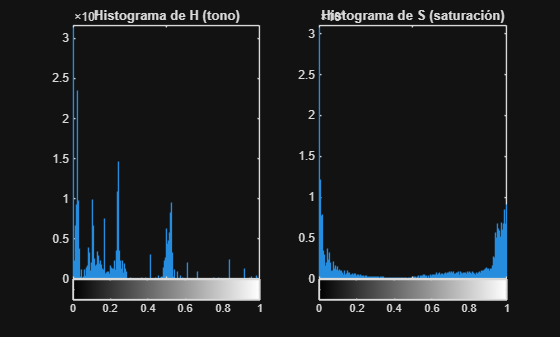

clear all
close all

info = imfinfo('.\Imagenes\eight.tif');
disp(info.ColorType);

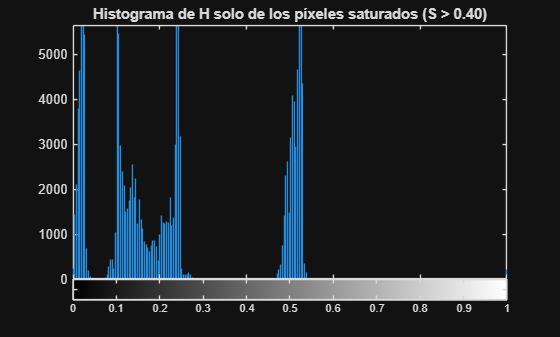


greyimg=imread('.\Imagenes\eight.tif'); %ya esta en escala de gris


umbral=graythresh(greyimg);
bin=imbinarize(greyimg, umbral);

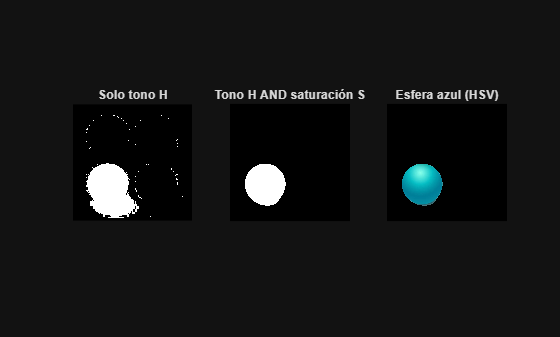


disp(['Umbral Otsu (0-1): ' num2str(umbral) '  ->  en niveles de gris: ' num2str(umbral*255)]);

figure;
subplot(1,2,1), imshow(greyimg);
subplot(1,2,2), imshow(bin);

figure;
imhist(greyimg);
hold on
xline(umbral*255, 'r');

hold off


%% Otsu sobre otras imágenes con histogramas de distinta forma
% Usamos un bucle para no repetir el mismo código 5 veces
nombres = {'coins.png', 'moon.tif', 'rice.png', 'cell.tif', 'circlesBrightDark.png'};


for k = 1:length(nombres)
    I = imread(['.\Imagenes\' nombres{k}]);
    I = im2gray(I); % por si alguna estuviera en color

    umbral = graythresh(I); % umbral de Otsu
    BW = imbinarize(I, umbral);

    figure;
    % Cada imagen ocupa una fila: original - histograma con umbral - resultado
    subplot(1, 3, 1), imshow(I);  title(nombres{k});
    subplot(1, 3, 2), imhist(I);  hold on
    xline(umbral*255, 'r'); hold off
    title(['T Otsu = ' num2str(round(umbral*255))]);
    subplot(1, 3, 3),   imshow(BW); title('Otsu');
end


%% PRUEBA EXTRA: eight.tif, Otsu frente a un umbral elegido a mano
I = imread('.\Imagenes\eight.tif');

grayscale


umbral = graythresh(I);

BW_otsu   = imbinarize(I, umbral); % umbral automático
BW_manual = I > 215; % umbral manual: justo antes del pico del fondo

figure;
subplot(1,3,1), imhist(I);
hold on

Umbral Otsu (0-1): 0.64902  ->  en niveles de gris: 165.5


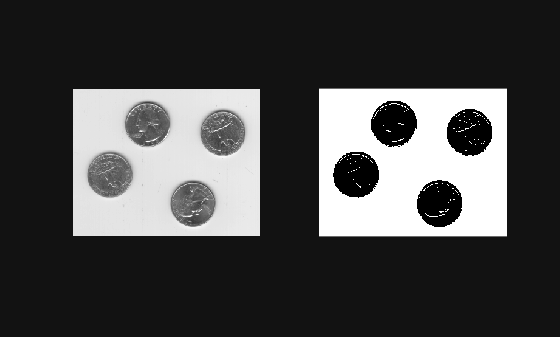

xline(umbral*255, 'r'); % rojo: Otsu
xline(215, 'g'); % verde: manual
hold off
title('Rojo: Otsu  -  Verde: manual');

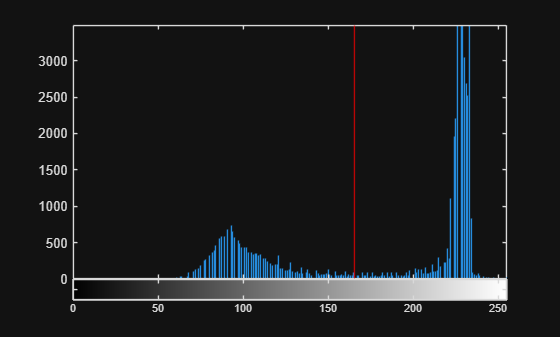

subplot(1,3,2), imshow(BW_otsu);   title('Otsu (T ≈ 165)');
subplot(1,3,3), imshow(BW_manual); title('Manual (T = 215)');

%% PRUEBA EXTRA: circlesBrightDark.png, 3 clases con Otsu multinivel (multithresh)
% Hay 3 clases (círculos negros, fondo gris, círculos blancos) y Otsu básico solo separa 2
I = im2gray(imread('.\Imagenes\circlesBrightDark.png'));


umbrales = multithresh(I, 2); % 2 umbrales -> 3 clases (devuelve niveles 0-255)
disp(umbrales);

% Imagen de etiquetas
etiquetas = zeros(size(I));
etiquetas(I <= umbrales(1)) = 1; % círculos oscuros
etiquetas(I > umbrales(1) & I <= umbrales(2)) = 2; % fondo gris
etiquetas(I > umbrales(2)) = 3; % círculos claros

figure;
subplot(1,3,1), imshow(I); title('Original');
subplot(1,3,2), imshow(imbinarize(I, graythresh(I))); title('Otsu 2 clases');
subplot(1,3,3), imshow(etiquetas, []); colormap(gca, jet);
title(['Otsu multinivel: T = ' num2str(umbrales(1)) ', ' num2str(umbrales(2))]);

En este apartado se ha aplicado la umbralización global no supervisada mediante el método de Otsu (graythresh + imbinarize), que calcula automáticamente el umbral maximizando la varianza entre clases.

En “eight.tif” se obtiene un umbral de 0,649. Las monedas se separan del fondo, pero la segmentación no es correcta: aparecen numerosos huecos y puntos blancos dentro de las monedas por los brillos.

El histograma está formado por un pico muy estrecho y dominante correspondiente al fondo (la mayor parte de los píxeles) y una distribución baja y muy ancha correspondiente a las monedas, de modo que Otsu sitúa el umbral en mitad de la distribución de las monedas y clasifica sus zonas más claras como fondo.

Un umbral elegido manualmente a la vista del histograma (T = 215, justo antes del pico del fondo) proporciona monedas un poco más macizas, aunque aparecen puntitos negros en el fondo y aun así se mantienen unos pocos agujeros en las monedas.

Al probar otras imágenes se observa que Otsu funciona bien cuando el histograma es bimodal, con los 2 lóbulos bien separados, y falla cuando la iluminación no es uniforme, cuando el histograma es unimodal porque objeto y fondo tienen niveles similares (“cell.tif”) o cuando existen más de dos clases (“circlesBrightDark.png”). Para este último caso, se ha probado a utilizar la extensión multinivel de Otsu (multithresh) con dos umbrales para comprobar que así sí se separan correctamente las tres clases de “circlesBrightDark.png”.

**3. Compare los dos apartados anteriores: umbralización supervisada frente a no supervisada, indicando las ventajas e inconvenientes de cada una.**

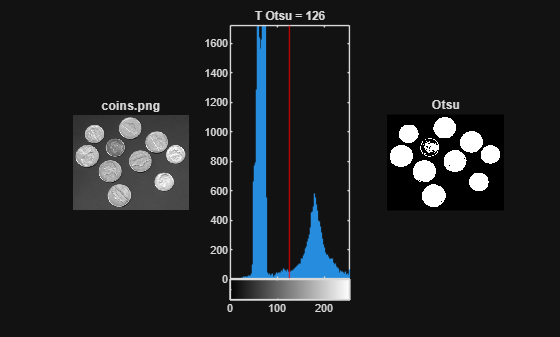

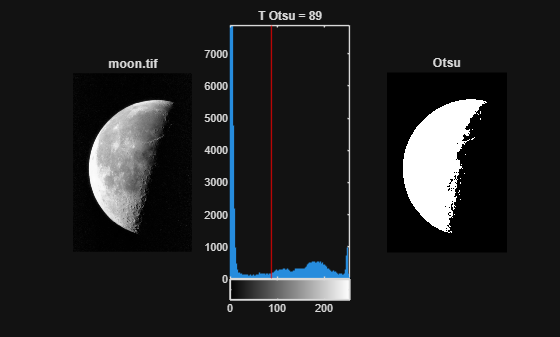

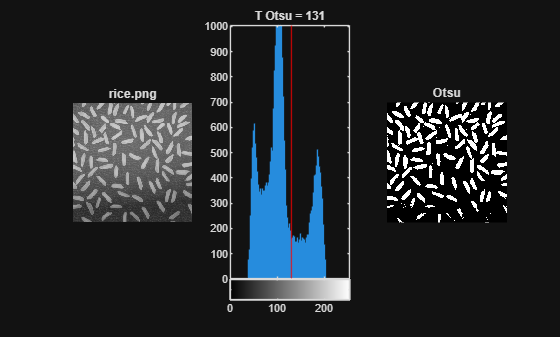

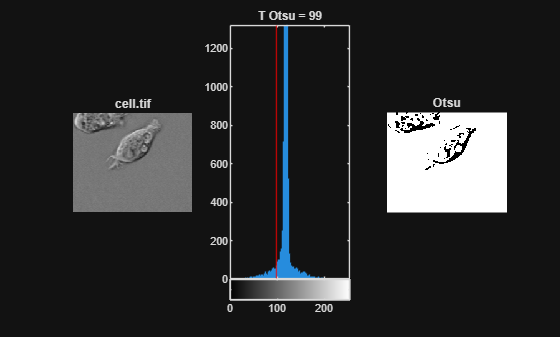

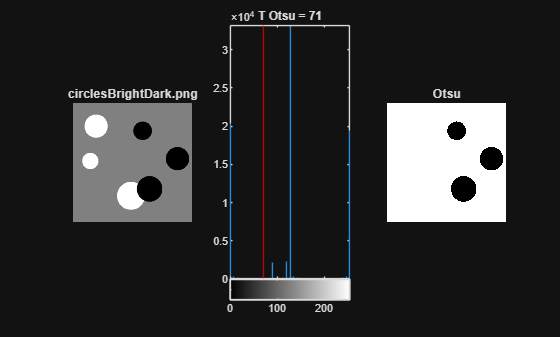

%% 3. COMPARACIÓN SUPERVISADA vs NO SUPERVISADA sobre la misma imagen (Esferas.jpg)
clear all
close all

X = imread('.\Imagenes\Esferas.jpg');
greyimg = im2gray(X);


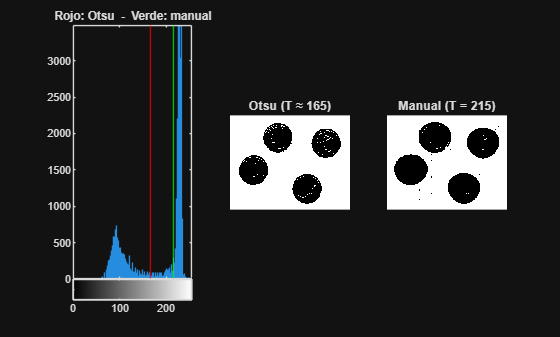

% --- Supervisada: umbrales elegidos a mano a la vista del histograma (apartado 1)
T_manual = [84 166 238];

% --- No supervisada: Otsu multinivel con el mismo número de umbrales (3 -> 4 clases)
T_otsu = multithresh(greyimg, 3);
disp(['Umbrales Otsu: ' num2str(T_otsu)]);

% Imagen de etiquetas con los umbrales manuales
etqManual = zeros(size(greyimg));
etqManual(greyimg <= T_manual(1)) = 1;
etqManual(greyimg > T_manual(1) & greyimg <= T_manual(2)) = 2;
etqManual(greyimg > T_manual(2) & greyimg <= T_manual(3)) = 3;
etqManual(greyimg > T_manual(3)) = 4;

% Imagen de etiquetas con los umbrales de Otsu
etqOtsu = zeros(size(greyimg));
etqOtsu(greyimg <= T_otsu(1)) = 1;
etqOtsu(greyimg > T_otsu(1) & greyimg <= T_otsu(2)) = 2;

etqOtsu(greyimg > T_otsu(2) & greyimg <= T_otsu(3)) = 3;
etqOtsu(greyimg > T_otsu(3)) = 4;

% Histograma con los dos juegos de umbrales
figure;
imhist(greyimg); hold on
for k = 1:3

    66   189



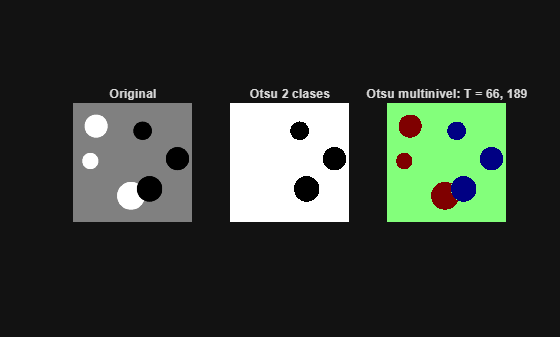

    xline(T_manual(k), 'g'); % verde: manual
    xline(T_otsu(k), 'r'); % rojo: Otsu
end
hold off
title('Verde: umbrales manuales  -  Rojo: umbrales Otsu');

figure;
subplot(1,3,1), imshow(X); title('Original');
subplot(1,3,2), imshow(etqManual, []); colormap(gca, jet); title('Supervisada (manual)');
subplot(1,3,3), imshow(etqOtsu, []); colormap(gca, jet); title('No supervisada');

%Prueba en rgb: SUPERVISADA (umbrales RGB a mano) vs NO SUPERVISADA (k-means en RGB)

R = X(:,:,1);  G = X(:,:,2);  B = X(:,:,3);

% SUPERVISADA: reglas elegidas a mano mirando los histogramas de R, G y B (apartado 1)
manual = zeros(size(R)); % 0 = fondo
manual((R > 200) & (G > 140) & (B < 140)) = 1; % amarilla
manual((R < 150) & (G > 100) & (B < 110)) = 2; % verde
manual(R <= 55) = 3; % azul
manual((R > 150) & (G < 140) & (B < 140)) = 4; % roja

% NO SUPERVISADA: k-means agrupa los píxeles por su vector de color (R,G,B)
rng(1); % fija la inicialización aleatoria (resultado repetible)
[kmedias, centroides] = imsegkmeans(X, 5); % 5 clases: 4 esferas + fondo
disp('Centroides encontrados por k-means (R G B):');
disp(centroides); % el color medio de cada clase

figure;
subplot(1,3,1), imshow(X); title('Original');
subplot(1,3,2), imshow(manual, []); colormap(gca, jet);
title('Supervisada');
subplot(1,3,3), imshow(kmedias, []); colormap(gca, jet);
title('No supervisada: k-means (k=5)');

La umbralización supervisada permite introducir el conocimiento del usuario sobre las clases que se quieren separar: los umbrales se sitúan en los valles del histograma que realmente separan objetos, se pueden ajustar varias clases y reducir algunos errores de sombras y brillos, aunque no siempre se eliminan. Su principal inconveniente es que requiere la intervención del usuario (o una fase de entrenamiento con muestras etiquetadas), es subjetiva y debe repetirse si cambian la imagen o las condiciones de captura, por lo que no es práctica para procesar muchas imágenes.

La umbralización no supervisada de Otsu es automática, rápida y reproducible, y da buenos resultados cuando el histograma es bimodal con lóbulos bien separados. El criterio tiene en cuenta los pesos y las medias de las clases, pero no sabe cuáles son los objetos de interés. Puede dar malos resultados si sus histogramas se solapan o tienen formas y tamaños muy distintos. graythresh separa dos clases; con multithresh se indica cuántos umbrales queremos.

Se comprobó al aplicar Otsu multinivel (multithresh, 3 umbrales) a “Esferas.jpg”: los umbrales obtenidos (111, 162 y 220) agrupan el fondo y algunas luces muy claras en una clase, la mayor parte de las esferas roja, verde y azul en otra clase, la amarilla en otra junto a las luces de las esferas verde y azul, y las sombras más claras, y la otra clase se las asigna a niveles intermedios de luces y sombras en determinadas esferas. Con los umbrales elegidos manualmente cada lóbulo corresponde en general a un objeto (fondo, esfera amarilla, azul-verde y roja). Lo mismo ocurrió en “eight.tif”, donde un umbral manual segmentó las monedas mejor que el de Otsu.

Por último, ambas técnicas comparten la limitación de basarse únicamente en el histograma: no utilizan información espacial y no pueden separar objetos con el mismo nivel de gris, para lo que es necesario elegir otras características, como las componentes de color. Por esto, como prueba adicional se comparó la segmentación supervisada en RGB del apartado 1 (umbrales elegidos manualmente sobre los histogramas de R, G y B, combinados con AND) con una segmentación no supervisada mediante k-means sobre el vector de color (R, G, B) con k = 5. Ambos métodos separan las cuatro esferas y el fondo y en general coinciden. Se ha fijado la semilla aleatoria para poder repetir el resultado mostrado.

Los centroides obtenidos automáticamente por k-means corresponden prácticamente a los colores reales de cada esfera, sin necesidad de observar ningún histograma, aunque con errores en las sombras y algunas luces. Con los umbrales manuales se pudo excluir explícitamente un poco más las sombras (exigiendo B bajo), mientras que k-means las asigna a la esfera cuyo color se parece más, porque no tiene información sobre qué es objeto y qué no.

En este caso, la segmentación no supervisada consigue resultados muy cercanos a la supervisada de forma automática y reproducible, siempre que se le indique el número de clases y que las características elegidas (el color) separen bien los objetos. La supervisada, en cambio, permite incorporar conocimiento del problema (descartar sombras, decidir qué hacer con los brillos) a costa de requerir la intervención del usuario.

Además, el resultado de k-means en color contrasta con el de Otsu multinivel en niveles de gris, que agrupaba tres esferas en la misma clase. Esto confirma que, más que la elección entre método supervisado o no supervisado, lo determinante es elegir adecuadamente las características utilizadas para segmentar.

**4. Opcional. Segmentación no lineal (mediante modelos gaussianos) con más de dos clases.**

En ambos casos se considerará que a la entrada se pueden utilizar imágenes de cualquier tamaño y tipo (indexadas, en color o en niveles de gris) que serán siempre convertidas a niveles de gris en primer lugar. La salida deberá ser una imagen de etiquetas que permita distinguir las distintas clases obtenidas.

- Implemente un programa que realice la segmentación supervisada por modelos gaussianos (no lineal) para un número de clases superior a 2.

- Implemente un programa que realice la segmentación no supervisada por modelos gaussianos (no lineal) para un número de clases superior a 2. 

%% SEGMENTACIÓN SUPERVISADA NO LINEAL (modelos gaussianos), más de 2 clases
clear all
close all

Umbrales Otsu: 111  162  220


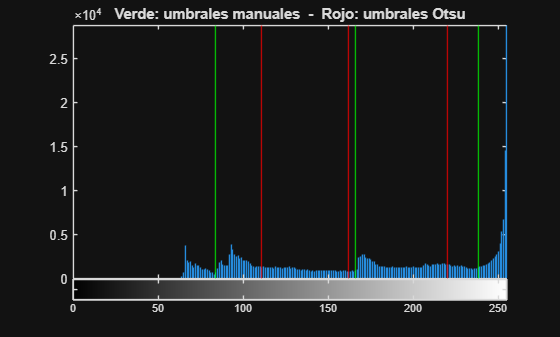


% Repetimos el mismo cálculo con dos imágenes de distinto tamaño y tipo.
% Esferas es RGB (693x709) y cameraman ya está en gris (256x256).
archivos = {'Esferas.jpg', 'cameraman.tif'};

for ejemplo = 1:numel(archivos)
    I = leerEnGris(['.\Imagenes\' archivos{ejemplo}]);

    % ---- 1) ENTRENAMIENTO: muestras de cada clase ----
    % Cada fila es un rectángulo: [fila_inicio fila_fin columna_inicio columna_fin].
    % Sólo cambian las muestras del ejemplo; el cálculo de abajo es el mismo.
    if ejemplo == 1
        nombresClases = {'roja', 'verde+azul', 'amarilla', 'fondo'};
        rectangulos = { [400 545 420 570], ...
                       [110 260 420 570; 400 545 130 280], ...
                       [110 260 130 280], ...
                       [1 60 1 700] };
    else
        nombresClases = {'zonas oscuras', 'terreno', 'cielo'};
        rectangulos = { [90 130 50 75], ...
                       [210 240 160 220], ...
                       [10 45 160 230] };
    end
    numClases = numel(nombresClases);

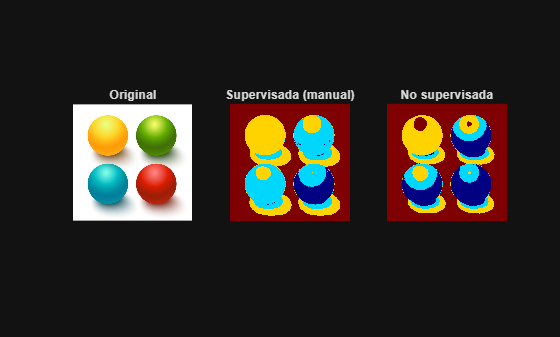

    medias = zeros(1, numClases);
    sigmas = zeros(1, numClases);

    % Con los píxeles de cada zona elegida calculamos su gris medio y cuánto varía.
    for k = 1:numClases

        mascara = false(size(I));
        r = rectangulos{k};
        for j = 1:size(r, 1) % una clase puede tener varios rectángulos
            mascara(r(j,1):r(j,2), r(j,3):r(j,4)) = true;
        end
        muestras = double(I(mascara));  % niveles de gris de las muestras
        medias(k) = mean(muestras);
        sigmas(k) = std(muestras);
    end

    % Si una clase tiene todos sus píxeles iguales (fondo blanco puro), su sigma es 0
    % y la gaussiana dividiría por cero. Le ponemos un mínimo de 1 nivel de gris.
    sigmas = max(sigmas, 1);
    % Todas las clases tienen la misma probabilidad previa: el tamaño de los
    % rectángulos de muestra no indica qué proporción ocupa cada clase.

Centroides encontrados por k-means (R G B):


    P = ones(1, numClases) / numClases;

   249   249   248
    89   140    18
   223   188    78
   196    46    24
    26   163   175



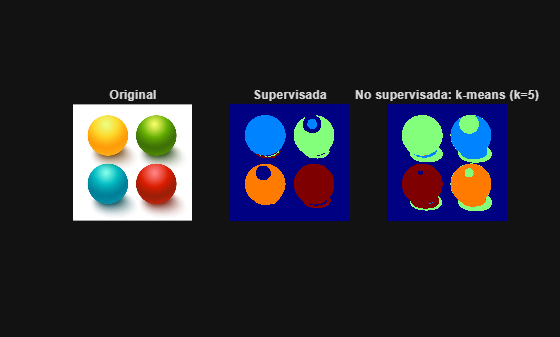


    fprintf('\nSupervisada: %s\n', archivos{ejemplo});
    for k = 1:numClases
        fprintf('%-14s media = %6.1f   sigma = %5.1f   P = %.3f\n', ...
            nombresClases{k}, medias(k), sigmas(k), P(k));
    end


    % ---- 2) CLASIFICACIÓN: cada píxel a la clase con mayor P*gaussiana ----
    [etiquetas, tabla] = clasificaGauss(I, medias, sigmas, P);
    umbrales = find(diff(tabla) ~= 0);
    disp('Cambios de clase (primer nivel de la clase siguiente):'); disp(umbrales);

    % ---- 3) VISUALIZACIÓN ----
    % Dibujamos las distribuciones estimadas junto al histograma de la imagen.
    z = 0:255;
    figure;
    imhist(I); hold on
    for k = 1:numClases
        curva = numel(I) * P(k) * exp(-(z-medias(k)).^2/(2*sigmas(k)^2)) / (sigmas(k)*sqrt(2*pi));
        plot(z, curva);
    end
    for u = umbrales
        xline(u, 'r--');
    end
    hold off
    title(['Supervisada: histograma y gaussianas - ' archivos{ejemplo}]);
    if ejemplo == 1
        ylim([0 5000]); % recortamos el gran pico del fondo blanco de las esferas
    end

    figure;
    subplot(1,2,1), imshow(I); title(archivos{ejemplo});
    subplot(1,2,2), imshow(etiquetas, []); colormap(gca, jet); colorbar;
    title(['Supervisada: ' num2str(numClases) ' clases']);
end

%% SEGMENTACIÓN NO SUPERVISADA NO LINEAL (EM / GMM), más de 2 clases
clear all
close all
% Repetimos el ajuste con las dos imágenes, indicando cuántas clases buscamos.
archivos = {'Esferas.jpg', 'cameraman.tif'};
clasesPorImagen = [5 3];

for ejemplo = 1:numel(archivos)
    I = leerEnGris(['.\Imagenes\' archivos{ejemplo}]);
    numClases = clasesPorImagen(ejemplo);
    datos = double(I(:)); % todos los píxeles en una columna

    % EM busca grupos de niveles de gris usando todos los píxeles,
    % sin que tengamos que señalar ejemplos de cada clase.
    % La regularización evita varianzas nulas y se prueban tres ajustes.
    rng(1); % fijamos la semilla para poder repetir el resultado
    opciones = statset('MaxIter', 1000);
    modelo = fitgmdist(datos, numClases, 'RegularizationValue', 1, ...
        'Replicates', 3, 'Options', opciones);
    fprintf('\nNo supervisada: %s. Convergido: %d   Iteraciones: %d\n', ...
        archivos{ejemplo}, modelo.Converged, modelo.NumIterations);

    medias = modelo.mu(:)';
    sigmas = sqrt(modelo.Sigma(:))'; % Sigma contiene las varianzas
    P = modelo.ComponentProportion; % ahora las probabilidades se estiman con toda la imagen

    % Ordenamos las clases de oscuro a claro para interpretar las etiquetas.
    [medias, orden] = sort(medias);
    sigmas = sigmas(orden);
    P = P(orden);
    for k = 1:numClases
        fprintf('Clase %d   media = %6.1f   sigma = %5.1f   P = %.3f\n', ...
            k, medias(k), sigmas(k), P(k));
    end

    % Con el modelo aprendido asignamos una clase a cada píxel.
    [etiquetas, tabla] = clasificaGauss(I, medias, sigmas, P);
    umbrales = find(diff(tabla) ~= 0);
    disp('Cambios de clase:'); disp(umbrales);

    % Mostramos cómo se ajustan las gaussianas al histograma y vemos las etiquetas.
    z = 0:255;
    figure;
    imhist(I); hold on
    for k = 1:numClases
        curva = numel(I) * P(k) * exp(-(z-medias(k)).^2/(2*sigmas(k)^2)) / (sigmas(k)*sqrt(2*pi));
        plot(z, curva);
    end
    for u = umbrales
        xline(u, 'r--');
    end
    hold off
    if ejemplo == 1
        ylim([0 5000]);
    end
    title(['No supervisada: histograma y gaussianas - ' archivos{ejemplo}]);

    figure;
    subplot(1,2,1), imshow(I); title(archivos{ejemplo});
    subplot(1,2,2), imshow(etiquetas, []); colormap(gca, jet); colorbar;
    title(['No supervisada: ' num2str(numClases) ' clases']);
end

Se han implementado dos programas de segmentación mediante modelos gaussianos para más de dos clases. Los hemos probado con Esferas.jpg y cameraman.tif, que tienen distinto tamaño y tipo. También admiten imágenes indexadas: primero se convierten a niveles de gris y al final se obtiene una imagen de etiquetas. Para probar otra imagen, indicamos su archivo y elegimos sus muestras en el caso supervisado o el número de clases en el no supervisado.

En ambos programas cada clase se representa con una gaussiana y cada nivel de gris se asigna a la clase con mayor Pk*pk(z). Calculamos esa asignación para los 256 niveles y después la aplicamos a todos los píxeles. En el supervisado obtenemos la media y la desviación de las zonas elegidas. Usamos probabilidades previas iguales porque el tamaño de esas zonas no indica cuánto ocupa cada clase en la imagen; si se cambian, pueden moverse los límites entre clases. En el no supervisado, EM obtiene los parámetros y las proporciones a partir de todos los píxeles, indicando solo cuántas clases buscamos.

Durante la implementación surgió un problema con el fondo blanco de Esferas.jpg: en una zona uniforme todos los píxeles tienen el mismo valor, la desviación es cero y la gaussiana no se puede calcular. Por eso fijamos un mínimo de 1 para la desviación. En EM usamos una regularización para evitar varianzas nulas. Además, el ajuste de Esferas necesitó más de 100 iteraciones; ampliamos el máximo a 1000 y comprobamos con Converged que el modelo obtenido había convergido.

En Esferas.jpg ninguno de los dos resultados mejora claramente los umbrales manuales del apartado 1. Los brillos y el degradado de iluminación hacen que las distribuciones de gris de algunas esferas sean anchas o asimétricas. En el no supervisado, una gaussiana recoge el fondo blanco y otras separan zonas de distinta iluminación de las esferas, que no siempre corresponden a objetos completos. El modelo ajusta los niveles de gris, pero no sabe qué regiones queremos considerar objetos.

En cameraman.tif las tres clases distinguen aproximadamente las zonas oscuras, el terreno y el cielo, aunque los detalles con intensidades parecidas se mezclan. Estos modelos pueden ser útiles cuando las distribuciones de las clases se aproximan bien con gaussianas, pero no garantizan un resultado mejor que los umbrales elegidos manualmente.


%% FUNCIONES LOCALES

function I = leerEnGris(fichero)
% Lee una imagen de CUALQUIER tipo y la devuelve en niveles de gris uint8 (0-255)


Supervisada: Esferas.jpg


roja           media =   96.5   sigma =  27.8   P = 0.250
verde+azul     media =  135.3   sigma =  36.7   P = 0.250
amarilla       media =  199.0   sigma =  19.3   P = 0.250
fondo          media =  255.0   sigma =   1.0   P = 0.250


Cambios de clase (primer nivel de la clase siguiente):
   121   171   252




Supervisada: cameraman.tif


zonas oscuras  media =   12.7   sigma =   3.2   P = 0.333
terreno        media =  119.5   sigma =  32.7   P = 0.333
cielo          media =  168.6   sigma =   6.4   P = 0.333


Cambios de clase (primer nivel de la clase siguiente):
    25   156   186




No supervisada: Esferas.jpg. Convergido: 1   Iteraciones: 237


Clase 1   media =   96.3   sigma =  19.2   P = 0.213
Clase 2   media =  174.3   sigma =  27.4   P = 0.225
Clase 3   media =  222.9   sigma =  12.8   P = 0.090
Clase 4   media =  247.3   sigma =   4.2   P = 0.052
Clase 5   media =  254.8   sigma =   1.2   P = 0.420


Cambios de clase:
   131   209   241   252



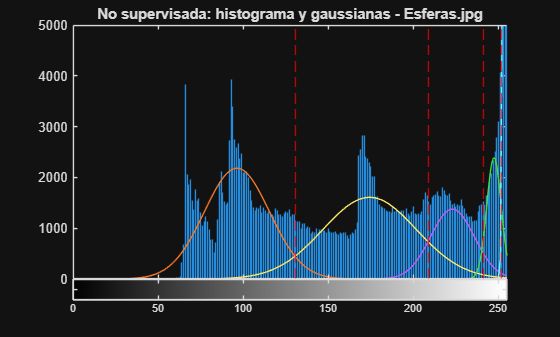

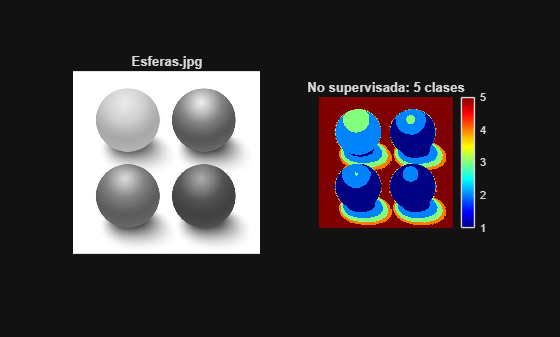


No supervisada: cameraman.tif. Convergido: 1   Iteraciones: 37


Clase 1   media =   12.9   sigma =   3.2   P = 0.190
Clase 2   media =  121.0   sigma =  44.5   P = 0.398
Clase 3   media =  165.4   sigma =  13.0   P = 0.412


Cambios de clase:
     3    23   144   196



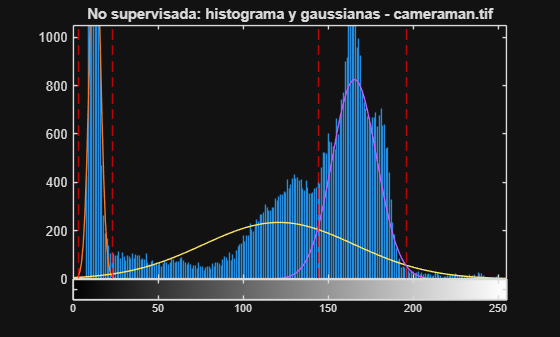

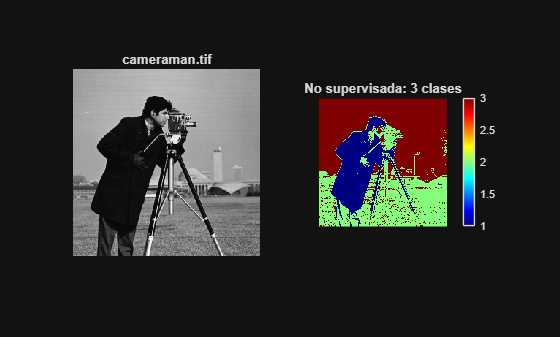

[I, map] = imread(fichero);
if ~isempty(map) % indexada: tiene mapa de color
    I = ind2gray(I, map);
elseif size(I, 3) == 3 % RGB
    I = rgb2gray(I);
end % si no, ya está en gris
I = im2uint8(I); % aseguramos uint8 0-255
end


function [etiquetas, tabla] = clasificaGauss(I, medias, sigmas, P)
% Asigna cada píxel a la clase k con mayor d_k(z) = P_k * gaussiana_k(z)
z = 0:255; % todos los niveles de gris posibles
numClases = numel(medias);
d = zeros(numClases, 256);
for k = 1:numClases
    d(k,:) = P(k) * exp(-(z - medias(k)).^2 / (2*sigmas(k)^2)) / (sigmas(k)*sqrt(2*pi));
end
[~, tabla] = max(d, [], 1); % tabla(z+1) = clase ganadora para el nivel z
etiquetas  = tabla(double(I) + 1); % se aplica la tabla a todos los píxeles de golpe
end